生成仿真用的数据

% [dataGenArgs] = dataGen(1);

执行外部解题程序，并读入程序的输出

system("..\build\x64-Release\main.exe");

Original newEdge.size = 87 
newEdge.size = 86 
newEdge.size = 87 
newEdge.size = 84 
newEdge.size = 87 
newEdge.size = 84 
newEdge.size = 83 
newEdge.size = 82 
newEdge.size = 81 
newEdge.size = 80 
newEdge.size = 81 
newEdge.size = 82 
newEdge.size = 83 
newEdge.size = 82 
newEdge.size = 80 
newEdge.size = 79 
newEdge.size = 81 
newEdge.size = 81 
newEdge.size = 81 
newEdge.size = 81 
Total Cost = 81319778 


[totCost, edgeStat, sortedEdgeStat, edgePile, transactionPassEdgeID, transactionMinPath] = readResult();

对结果进行可视化分析

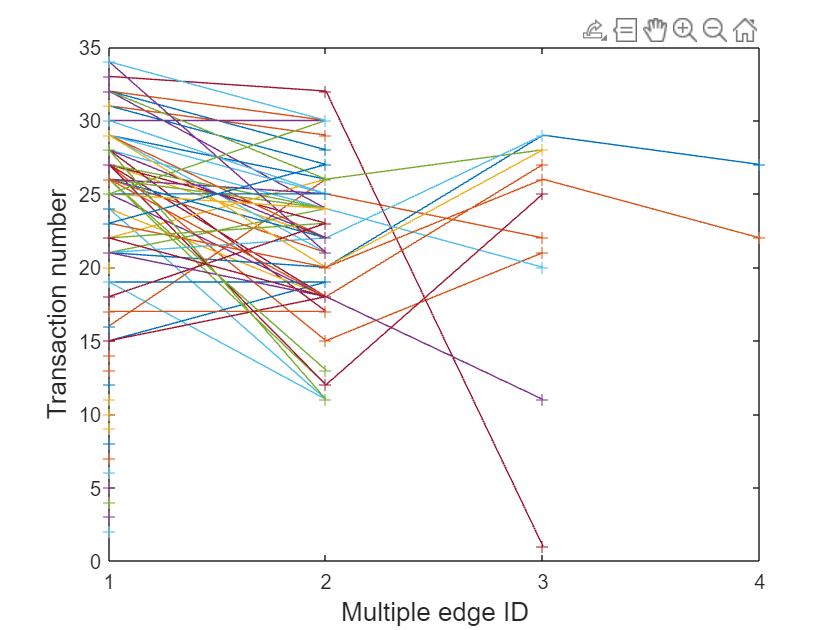

% [TransactionAllocation] = plotOverview(edgeStat);
[TranNumInMiltiEdge] = plotTranNumInMultiEdge(edgeStat);

transactionID = 499;
% plotUsedPilewithMinPath(transactionID, transactionMinPath, transactionPassEdgeID, edgeStat, edgePile);
% plotUsedPile3D(edgePile);

批量测试

% testTime = 20;
% costRecord = zeros(testTime, 2);
% for i = 1 : testTime
%     randomSeed = i;
%     [dataGenArgs] = dataGen(randomSeed);
%     costRecord(i, 1) = system("..\build\x64-Release\main.exe 0");
%     costRecord(i, 2) = system("..\build\x64-Release\main.exe 1");
% end
% plot(costRecord)